## Example_live.mlx

% Create path
clear all; close all; clc
addpath(genpath(cd)); % add all subfolders of cd to path

This live script runs auto_ultrasound.m, resulting in an estimation of muscle fascicle length and pennation angle. In this live script, parameters can be adjusted and their effect can be investigated. 

Tim van der Zee 2020-12-23, tim.vanderzee@ucalgary.ca

## Load and plot image

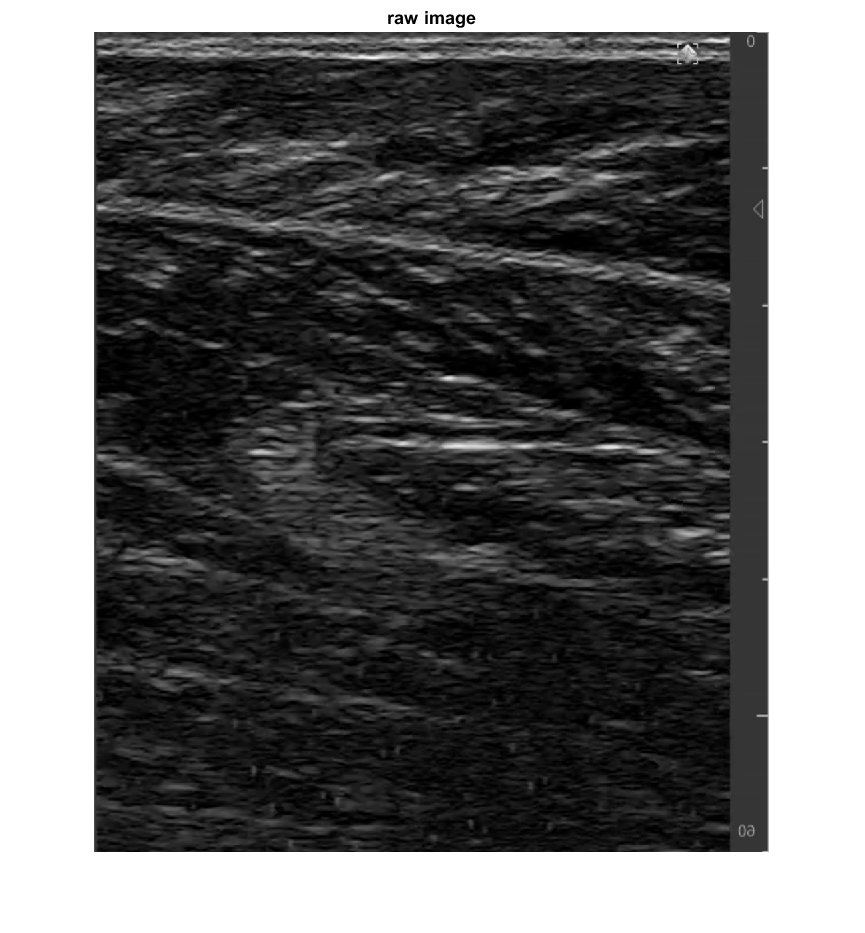

load('parms.mat'); % start with default parameters
load('Data\example_ultrasound_image.mat')
% data = flip(rgb2gray(imread('Data\example_ultrasound_image3.png')),2);
[n,m] = size(data); % data needs to be a n-by-m numeric array

figure; imshow(data); title('raw image')

## Frangi filtering

As described in the documentation of FrangiFilter2D, the function uses the eigenvectors of the Hessian to compute the likeliness of an image region to vessels, according to the method described by Frangi, 2001 (Chapter 2). Thinner lines can be detected by using small values for the range (fascicles), and thicker lines can be detected by using large values for the range (aponeuroses)

% aponeurosis filtering
parms.apo.frangi.FrangiScaleRange(1) = 18; % lower limit on thickness range (pixels)
parms.apo.frangi.FrangiScaleRange(2) = 19; % upper limit on thickness range (pixels)

% fascicle filtering
parms.fas.frangi.FrangiScaleRange(1) = 1; % lower limit on thickness range (pixels)
parms.fas.frangi.FrangiScaleRange(2) = 2; % upper limit on thickness range (pixels)

% do filtering
aponeurosis = FrangiFilter2D(double(data), parms.apo.frangi);

Current Frangi Filter Sigma: 18
Current Frangi Filter Sigma: 19


fascicle = FrangiFilter2D(double(data), parms.fas.frangi);

Current Frangi Filter Sigma: 1
Current Frangi Filter Sigma: 2


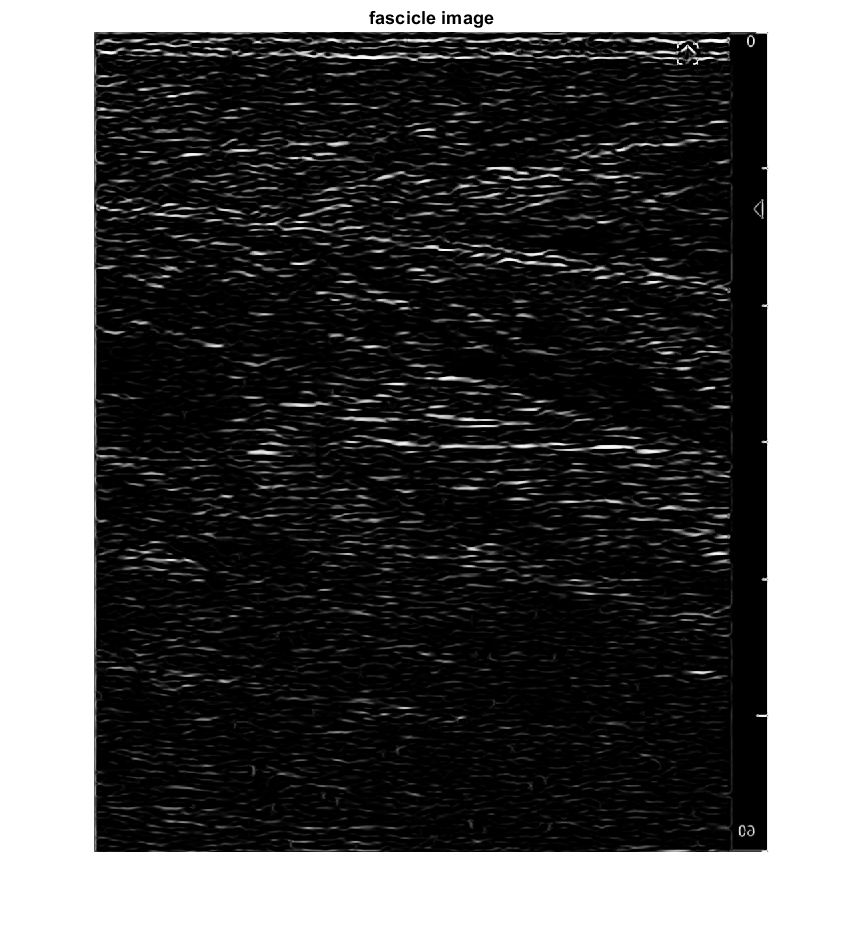


figure; imshow(fascicle); title('fascicle image')

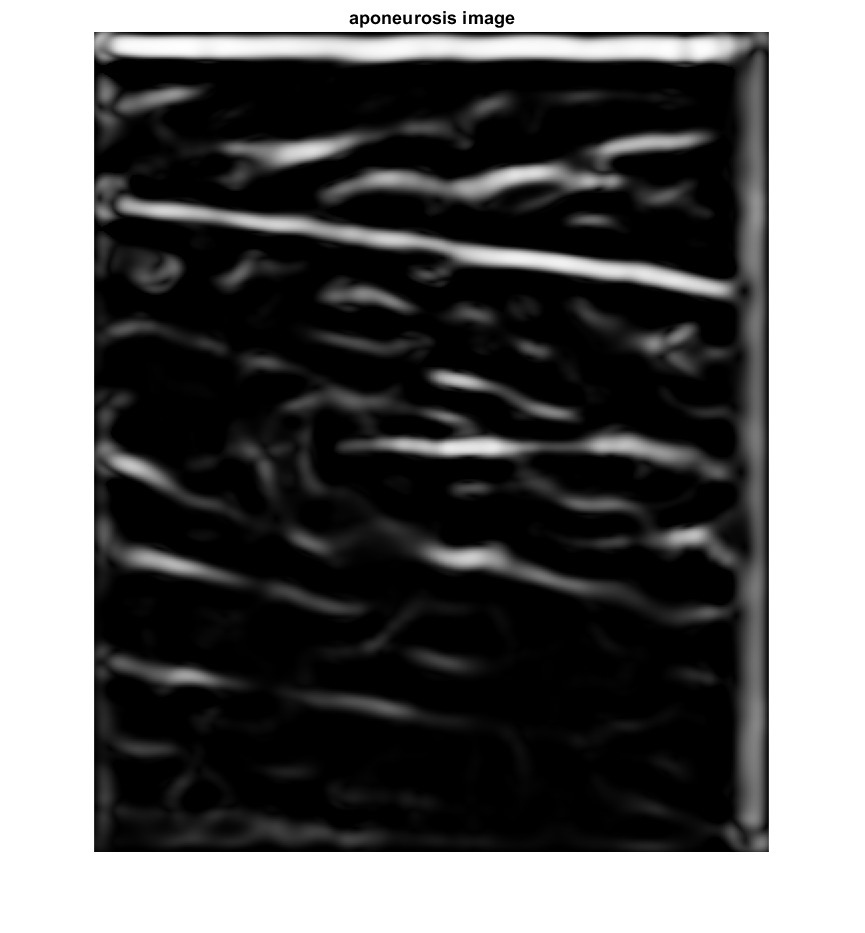

figure; imshow(aponeurosis); title('aponeurosis image')

## Specify parameters and determine alpha, betha, thickness

Current Frangi Filter Sigma: 18
Current Frangi Filter Sigma: 19
Current Frangi Filter Sigma: 1
Current Frangi Filter Sigma: 2


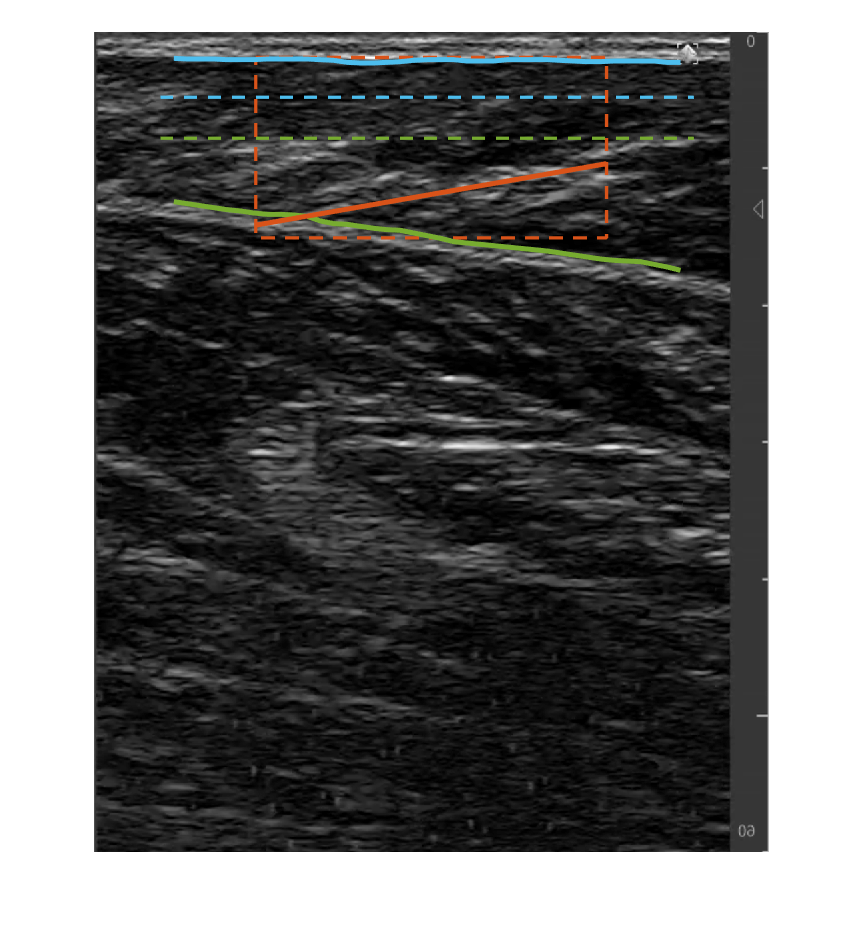

% Aponeurosis cutting
parms.apo.supercut = 0.08; % fraction of vertical ascribed to superficial aponeurosis
parms.apo.deepcut = 0.13; % fraction of vertical ascribed to deep aponeurosis

% Aponeurosis selection criteria
parms.apo.superrange(1) = -10; % smallest superficial aponeurosis angle considered (deg)
parms.apo.superrange(2) = 30; % largest superficial aponeurosis considered (deg)
parms.apo.deeprange(1) = -20; % smallest deep aponeurosis angle considered (deg)
parms.apo.deeprange(2) = 10; % largest deep aponeurosis considered (deg)
parms.apo.minlength = 200; % minimal length for aponeurosis object (pixels) 
parms.apo.maxlengthratio = 0.8; % maximal ratio between longest and second longest object
parms.apo.fillgap = 5; % gap filling in the aponeurosis (pixels)

% Define the horizontal aponeurosis spacing
apomargin = 100; % distance between start aponeurosis objects and the sides (pixels)
apospacing = 20; % horizontal spacing for aponeurosis (pixels) 
parms.apo.apox = apomargin:apospacing:(m-apomargin);

% Fascicle cutting
parms.fas.cut(1) = 0.11; % relative amount kept from the middle
parms.fas.cut(2) = 0.24; % relative amount cut on the sides

% Hough parameters arameters
parms.fas.range(1) = 10; % smallest fascicle angle considered (deg)
parms.fas.range(2) = 30; % largest fascicle angle considered (deg)
parms.fas.npeaks = 5; % amount of Hough angles included in weighted average

% Show figure?
parms.show = true;

% Run auto_ultrasound
[alpha, betha, thickness] = auto_ultrasound(data,parms);


% Display things
disp(['Fascicle angle = ' , num2str(round(alpha,3)), ' deg' ])

Fascicle angle = 10.974 deg


disp(['Superficial aponeurosis angle = ' , num2str(round(betha,3)), ' deg' ])

Superficial aponeurosis angle = -0.255 deg


disp(['Muscle thickness = ' , num2str(round(thickness,3)), ' pixels' ])

Muscle thickness = 262.51 pixels


## Fascicle length and pennation angle calculation

Based on geometry, pennation angle (phi) equals the difference between fascicle angle (alpha) and superficial aponeurosis angle (betha). Fascicle length (faslen) equals the ratio between muscle thickness and pennation angle. See Fig. 1 in *van der Zee & Kuo (2020a):* [https://www.biorxiv.org/content/10.1101/2020.08.23.263574v1](https://www.biorxiv.org/content/10.1101/2020.08.23.263574v1)

% Pixel to cm ratio
pixtocm = 115.25; % pix/cm

% Pennation angle (phi) and fascicle length
phi = alpha - betha;
faslen = (thickness/pixtocm) ./ sind(phi);

% Display pennation angle and fascicle length
disp(['Pennation angle = ' , num2str(round(phi,2)), ' deg' ])

Pennation angle = 19.21 deg


disp(['Fascicle length = ' , num2str(round(faslen,2)), ' cm'])

Fascicle length = -0.74 cm


## Application: energetic cost of cyclic muscle force production

Fascicle lengths and pennation angles may be used to estimate muscle moment arms and the amount of mechanical work done by the muscle. See *van der Zee & Kuo (2020b):* [https://www.biorxiv.org/content/10.1101/2020.08.25.266965v1](https://www.biorxiv.org/content/10.1101/2020.08.25.266965v1)